# E6

## Morfología multinivell

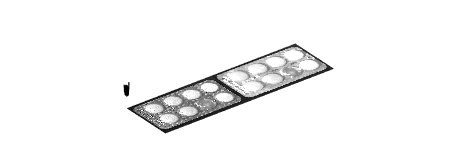

I = imread("astablet.tif");
ES = ones(5,5);
ID = imdilate(I, ES);
montage({I, ID});

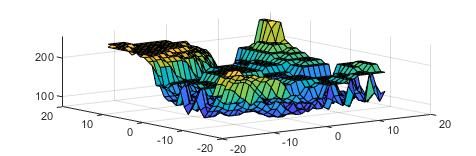


% Visualització en 3d
[f, c] = size(I);
f_2 = floor(f/2);
c_2 = floor(c/2);
Icrop = I(f_2 -15 : f_2 +15, c_2 -15 : c_2 +15);
IDcrop = ID(f_2 -15 : f_2 +15, c_2 -15 : c_2 +15);
[X, Y] = meshgrid(-15:15);
surf(X, Y, IDcrop);
% hold on
% surf(X, Y, Icrop)

% hold off

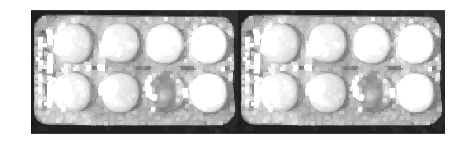

% Dilatacio = max dels veins
ID2 = colfilt(I, [5,5], 'sliding', @max);
montage({ID, ID2});

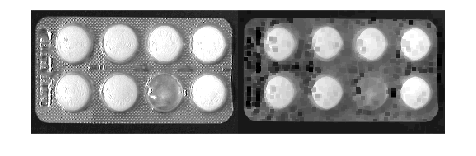

% Erode
IE = imerode(I, ES);
montage({I, IE});

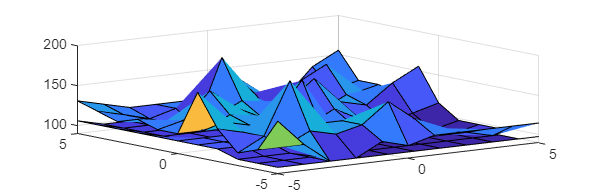

% Visualització en 3d
[f, c] = size(I);
f_2 = floor(f/2);
c_2 = floor(c/2);
Icrop = I(f_2 -5 : f_2 +5, c_2 -5 : c_2 +5);
IEcrop = IE(f_2 -5 : f_2 +5, c_2 -5 : c_2 +5);
[X, Y] = meshgrid(-5:5);
surf(X, Y, IEcrop);
hold on
surf(X, Y, Icrop)
hold off

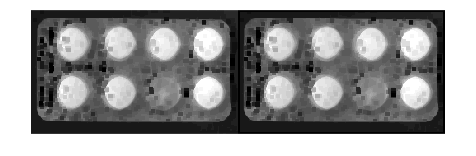

% Erosio = min dels veins
IE2 = colfilt(I, [5,5], 'sliding', @min);
montage({IE, IE2})

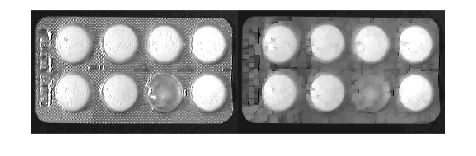

% Open
IO = imopen(I, ES);
montage({I, IO});

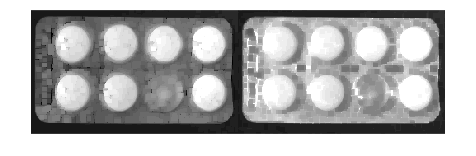

% Close
IC = imclose(I, ES);
montage({I, IC});

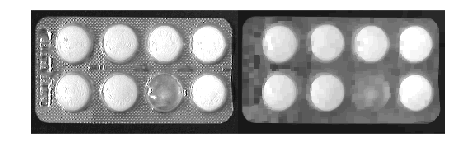

% Open + Close Filtre = elimina soroll
IOC = imclose(IO, ES);
montage({I, IOC});

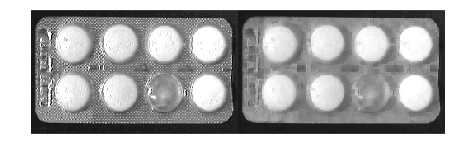

% Filtre
IOCF = uint8((double(IO) + double(IC)) / 2);
montage({I, IOCF});

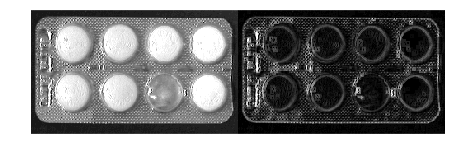

% Residus
I = imread('astablet.tif');
ES = ones(5,5);
IE = imerode(I, ES);
RI = I - IE; % enaltir contorn morfologic intern
montage({I, RI});

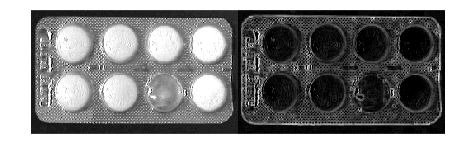


ID = imdilate(I, ES);
RE = ID - I; % enaltir contorn morfologic extern
montage({I, RE});

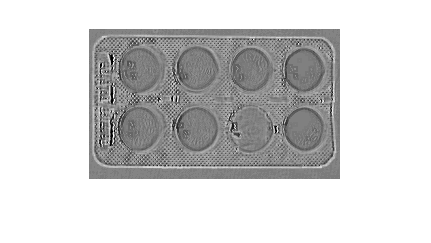


% Laplacia
L = double(RE) - double(RI);
imshow(L, [])

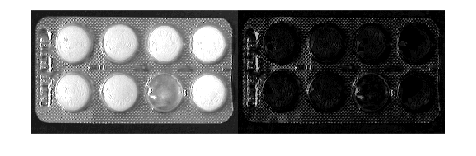

ES = ones(5,5);

IO = imopen(I, ES);
TH = I - IO;
montage({I, TH})

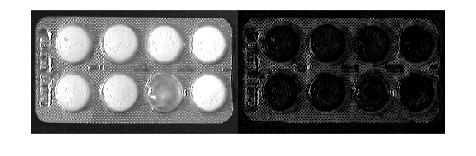


IC = imclose(I, ES);
BH = IC - I;
montage({I, BH})

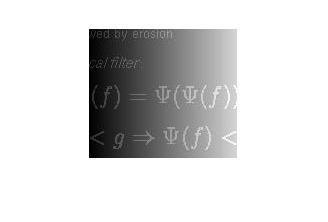

% Aplicació del top hat

I = imread("nshadow.tif");
imshow(I);

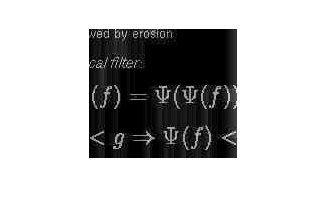


ES = ones(25, 25);
IO = imopen(I, ES);
TH = I - IO;
imshow(TH, []);

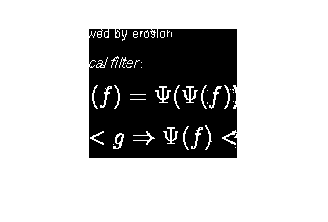


t = otsuthresh(imhist(TH));
imshow(TH > t * 255, []);

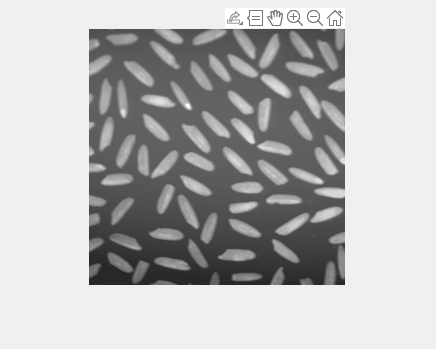

% Reconstruccio

I = imread("arros.tif");
imshow(I);
[y,x] = getpts;

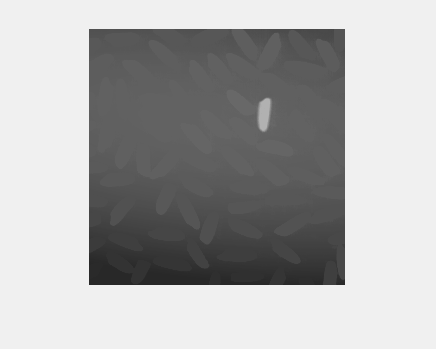

MARK = uint8(zeros(size(I)));

MARK(uint16(x),uint16(y)) = 255;
REC = imreconstruct(MARK, I);
imshow(REC);

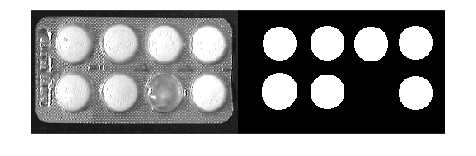

% Maxims regionals

I = imread("astablet.tif");
IRM = imregionalmax(I); % Masses maxims regionals per detectar les pastilles

% Filtrem
ES = fspecial("disk", 20) > 0; % ES = strel()
IO = imopen(I, ES);
IMR_filtered = imregionalmax(IO);

montage({I, IMR_filtered});

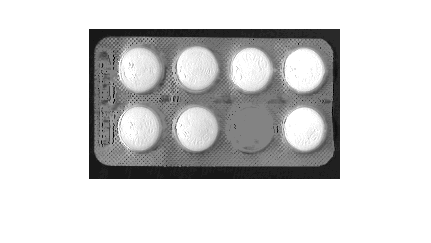


IM = I;
IM(not(IMR_filtered)) = 0;

REC = imreconstruct(uint8(IM), I);
imshow(REC)

### Exercici: Realitzar un plot de granulometria

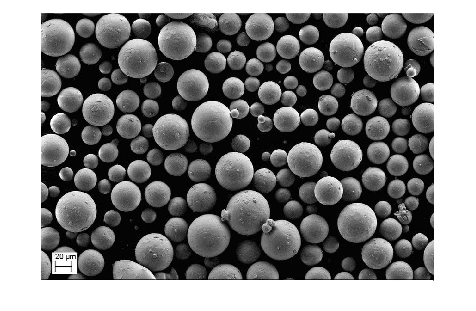

% Plot mostra mida vs nombre

I = imread("granulometria2.png");
imshow(I);

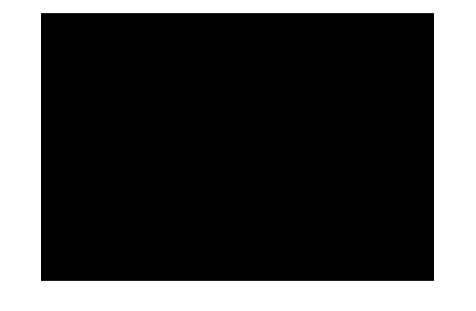


% 1 
results = zeros(50, 1);
for i = 1:50
    ES = fspecial("disk", i) > 0;
    IO = imopen(I, ES);
    t = otsuthresh(imhist(IO));
    t = max(32, t*255);
    BW = IO > t;
    imshow(BW);
    drawnow;
    results(i) = bwconncomp(BW).NumObjects;
end

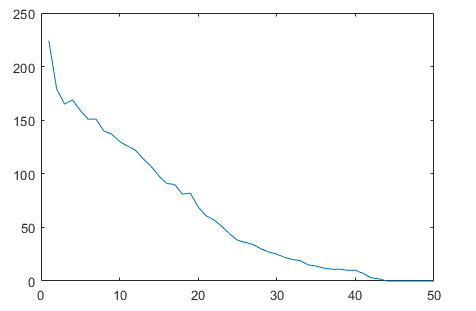


plot(results)